**Download Dataset**

This data has been pre-processed from [Steinmetz et al. (2019)](https://www.nature.com/articles/s41586-019-1787-x), and is hosted on Sciebo here: [https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J.](https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J.) The code below downloads the data into a directory named` data`

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo('https://uni-bonn.sciebo.de/s/wjsBtZzUVjKaB3J', 'data/steinmetz_all.csv')

Done!

addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

# Analyzing Behavioral Task Performance: Psychometric Analysis on Ordered Categorical Data

In the experiment reported on by [Steinmetz et al, 2019 in Nature](https://www.nature.com/articles/s41586-019-1787-x), mice were tasked with turning a wheel to the left or right based on the relative contrast levels of two simultaneously-presented gradient  stimuli:

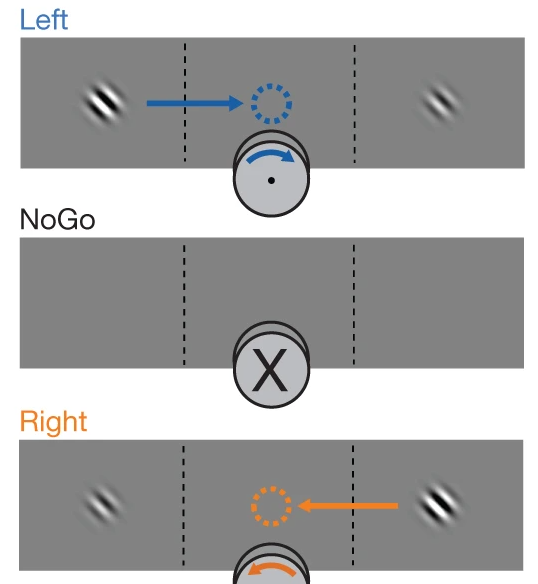

When the left stimuli is brightest, in order to earn a reward, the mouse must turn the wheel to the right. Accordingly when the right stimili is brightest, the mouse must turn the wheel to the right. When both stimili have equal contrasts (including the case where no stimili are shown), the correct response is not to turn the wheel. 

**Analysis Goal: **The `response_type` data encodes which way the mouse turned the wheel : -1 corresponds to a left turn, 1 to a right turn and 0 means that the wheel was not turned at all.   In this notebook, we'll examine the `response_time` and `response_type` of each trial across all sessions, to determine whether the mice  successfully performed the task, and whether the difference in contrast  levels between the two stimuli affected their performance.

## Calculating Group Statistics with `grpstats()`

How do the statistics on `response_time` and `response_type` change when the data is broken down into various groups?  In this section, we'll practice using the `grpstats()` function to do this with tables. 

`grpstats()` is a rich function that makes it possible to do a wide variety of analyses on a single line. It needs four pieces of information:

- The **Table **it should do the calculation on.

- The **Grouping Variable(s)** in the table that it should reference to know how break down the dataset.

- The **Statistic(s)** that is should apply to each group.  

- The **Data Variables(s)** in the table that the statistics should be applied to.

**Exercises**

We'll use the `tableread` function to load in data from a CSV file called `steinmetz_all.csv. `

Name the table `data`

data = readtable("data/steinmetz_all.csv")

data = 14420×16 table
    Var1    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id
    ____    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ________    ___

**Example: **Make a table showing the median response time for each `contrast_left` level.

grpstats(data, "contrast_left", "median", "DataVars", "response_time")

ans = 4×3 table
           contrast_left    GroupCount    median_response_time
           _____________    __________    ____________________

    0             0            7200              1.8906       
    25           25            1680              1.0516       
    50           50            1696             0.98249       
    100         100            3844              1.0205       


Make a table showing the median response time for each `contrast_left` level.

grpstats(data, "contrast_right", "median", "DataVars", "response_time")

ans = 4×3 table
           contrast_right    GroupCount    median_response_time
           ______________    __________    ____________________

    0             0             5103              1.9046       
    25           25             2528              1.0682       
    50           50             2418              1.0152       
    100         100             4371             0.98016       


Make a table showing the number of trials that each mouse performed.

grpstats(data, "mouse", "numel", "DataVars", "trial");  % shorter version: groupsummary(data, "mouse")

ans = 10×3 table
                     mouse        GroupCount    numel_trial
                 _____________    __________    ___________

    Cori         {'Cori'     }       1143          1143    
    Muller       {'Muller'   }       1112          1112    
    Radnitz      {'Radnitz'  }       1512          1512    
    Moniz        {'Moniz'    }        896           896    
    Hench        {'Hench'    }       1851          1851    
    Theiler      {'Theiler'  }        453           453    
    Richards     {'Richards' }       1677          1677    
    Forssmann    {'Forssmann'}       1485          1485    
    Lederberg    {'Lederberg'}       2902          2902    
    Tatum        {'Tatum'    }       1389         

Make a table showing the median `response_time` for each combination of `contrast_left` and `contrast_right` levels.

grpstats(data, ["contrast_left", "contrast_right"], "median", "DataVars","response_time")

ans = 16×4 table
               contrast_left    contrast_right    GroupCount    median_response_time
               _____________    ______________    __________    ____________________

    0_0               0                0             2649               2.094       
    0_25              0               25              738              1.0911       
    0_50              0               50             1078              1.0372       
    0_100             0              100             2735              1.0686       
    25_0             25                0              353              1.2178       
    25_25            25               25              255              1.2346       
    25_50            25               50       

Make a table showing the number of trials that each mouse saw each combination of contrast_left and contrast_right levels

grpstats(data, ["mouse", "contrast_left", "contrast_right"], "numel", "DataVars","trial")

ans = 158×5 table
                     mouse      contrast_left    contrast_right    GroupCount    numel_trial
                    ________    _____________    ______________    __________    ___________

    Cori_0_0        {'Cori'}           0                0             188            188    
    Cori_0_25       {'Cori'}           0               25              53             53    
    Cori_0_50       {'Cori'}           0               50              89             89    
    Cori_0_100      {'Cori'}           0              100             127            127    
    Cori_25_0       {'Cori'}          25                0              41             41    
    Cori_25_25      {'Cori'}          25               25 

Let's make a mega statistics table.  Calculate the median, mean, and std, and `meanci` (95% confidence intervals of the mean) for both the response time and response type, for every combination of `contrast_left` and `contrast_right` levels, for each `session_id`.

grpstats(data, ["session_id", "contrast_left", "contrast_right"], ["median", "mean", "meanci"], "DataVars", ["response_type", "response_time"])

ans = 620×10 table
                    session_id    contrast_left    contrast_right    GroupCount    median_response_type    mean_response_type    meanci_response_type    median_response_time    mean_response_time    meanci_response_time
                    __________    _____________    ______________    __________    ____________________    __________________    ____________________    ____________________    __________________    ____________________

    5dd41e_0_0      {'5dd41e'}           0                0              46                   0                -0.086957         -0.23807    0.064156           2.1816                 

## **Plotting Group Statistics with **`bar() and` `plot()`

`As the saying goes, "A picture is worth a thousand words." In this section, we'll combine the grouping statistics calculation to make a summary table, which is then passed into a plotting function.  `

**Exercises**

*Example*: Make a bar plot showing the mean response type for each `contrast_right` level

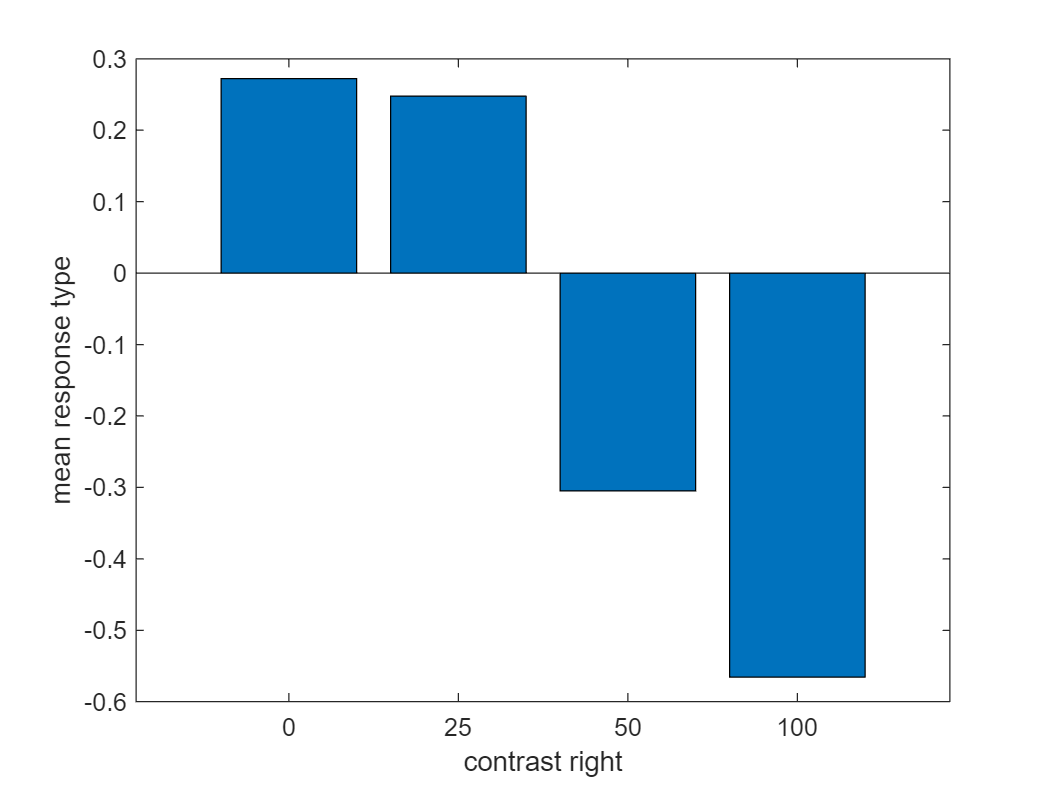

summ = grpstats(data, "contrast_right", "mean", "DataVars", "response_type");
bar(categorical(summ.contrast_right), summ.mean_response_type)
xlabel("contrast right")
ylabel("mean response type")

Make a bar plot showing the mean response type for each `contrast_left` level

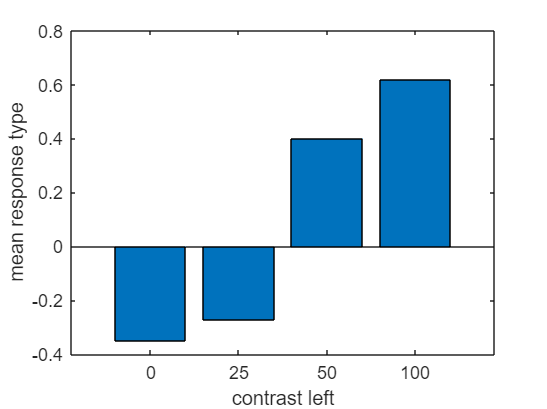

summ = grpstats(data, "contrast_left", "mean", "DataVars", "response_type");
bar(categorical(summ.contrast_left), summ.mean_response_type)
xlabel("contrast left")
ylabel("mean response type")

Make a bar plot showing the mean reaction type for each mouse.

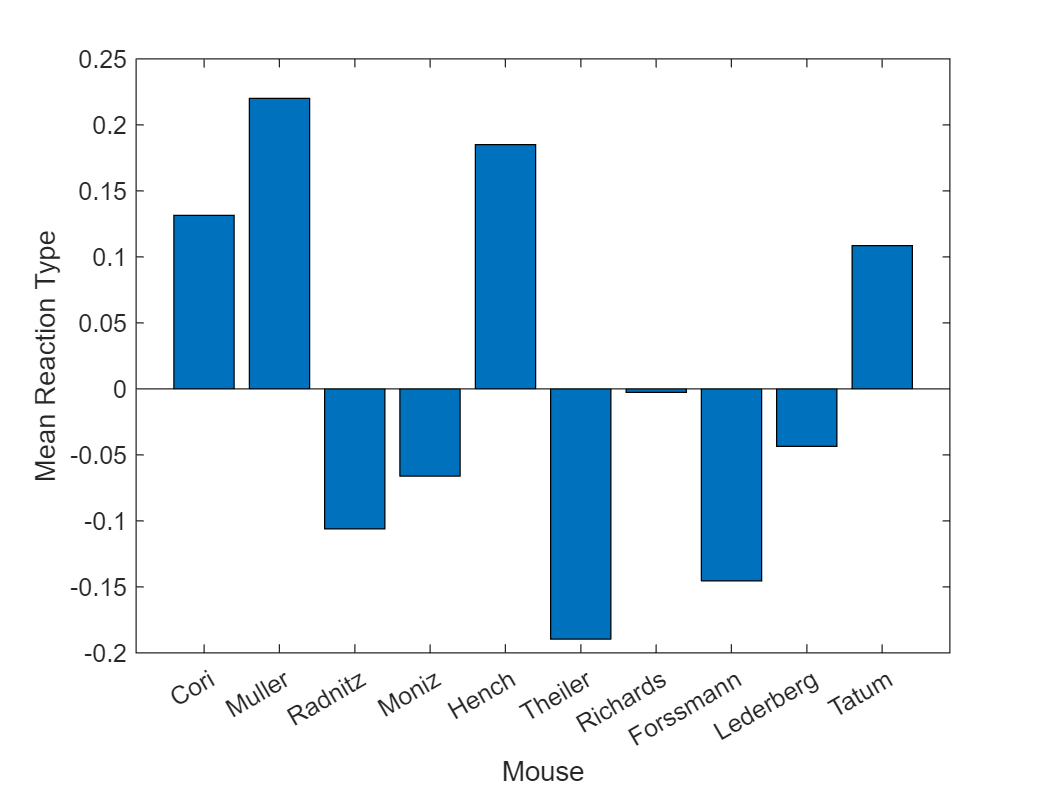

summ = grpstats(data, "mouse", "mean", "DataVars", "reaction_type");
bar(summ.mouse, summ.mean_reaction_type)
xlabel("Mouse")
ylabel("Mean Reaction Type")

Make a bar plot showing the median reaction time for each mouse.

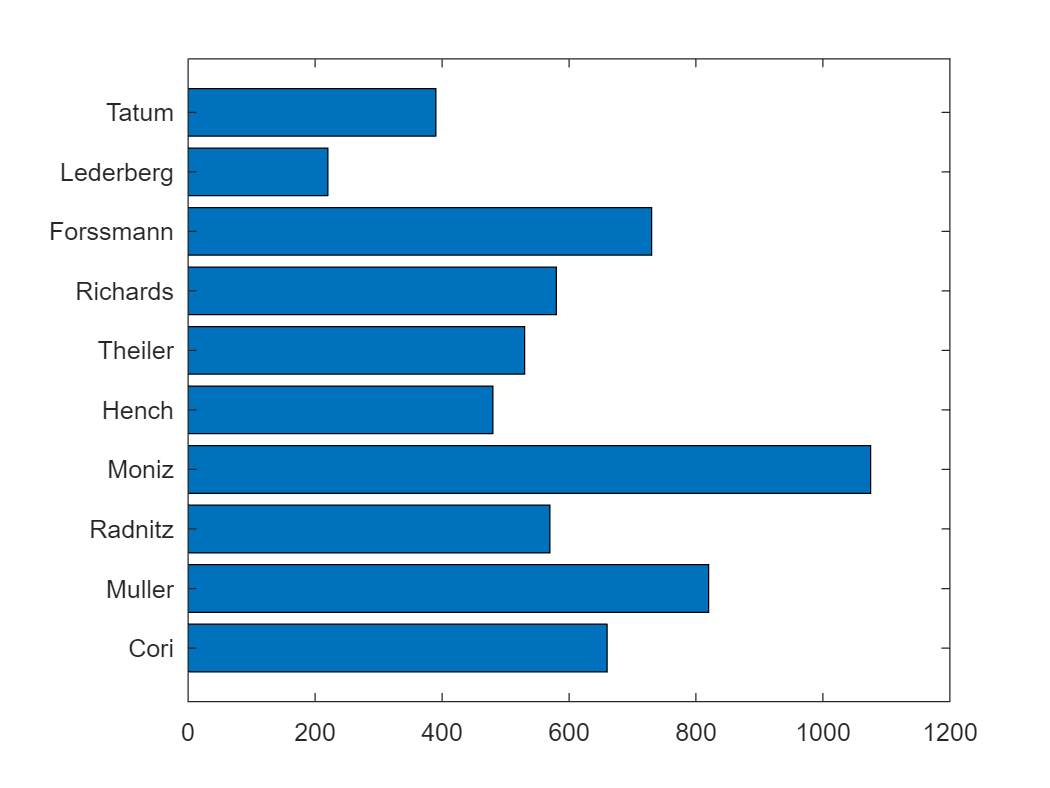

summ = grpstats(data, "mouse", "median", "DataVars", "reaction_time");
barh(summ.mouse, summ.median_reaction_time)

xlabel("Mouse")
ylabel("Median Reaction Time")

## Calculating Group Statistics on Transformed Data

Making new columns in MATLAB tables

In the exercises below, let's practice making new columns in our table, and use them in new grouped statistics calculations.

**Exercises**

*Example: *Make a new column called `contrast_total` that is the sum of the two stimuli's contrast levels.  Make a plot showing how median response time changes with `contrast_total`.

% Calculate New Value
data.contrast_total = data.contrast_left + data.contrast_right

data = 14420×17 table
    Var1    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id    contrast_total
    ____    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    

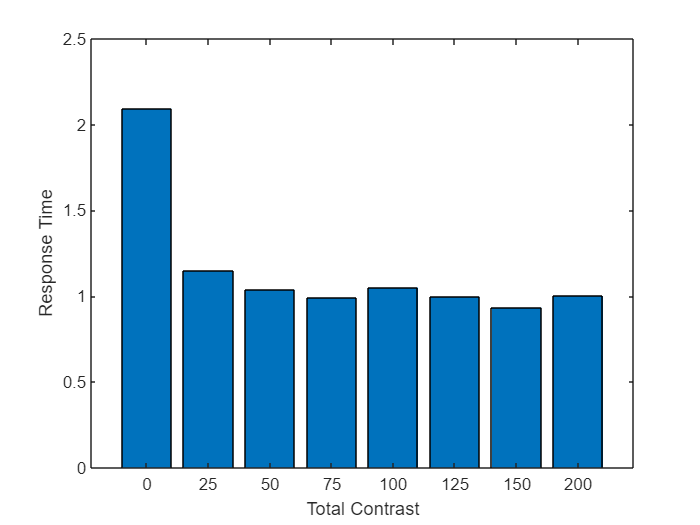


% Calculate Group Statistics
summ = grpstats(data, "contrast_total", "median", "DataVars", "response_time");

% Make Plot
bar(categorical(summ.contrast_total), summ.median_response_time)
xlabel('Total Contrast')
ylabel('Response Time')

The mice had to make a decision of whether to move the wheel left or right based on the *difference* in contrast between the left and right stimulus, not on the actual levels of the data. 

Make a new column called `contrast_diff` that contains the contrast difference between the left and right stimuli.  Make a plot showing how mean `response_type` changes with `contrast_diff`.

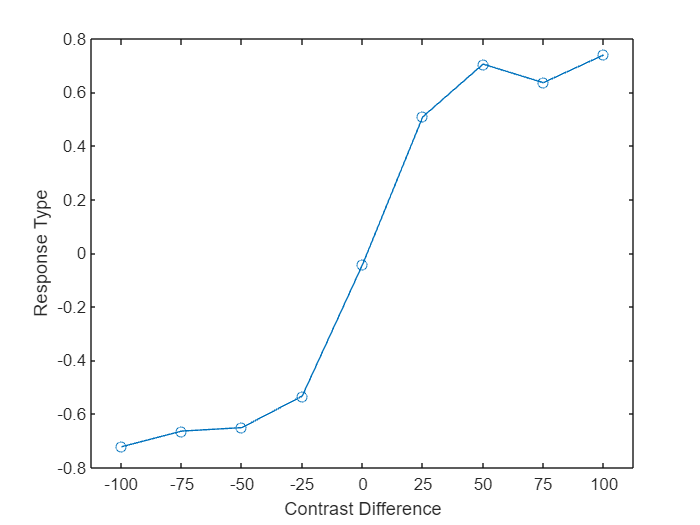

% Calculate New Value
data.contrast_diff = data.contrast_left - data.contrast_right;

% Calculate Group Statistics
summ = grpstats(data, "contrast_diff", "mean", "DataVars", "response_type");

% Make Plot
plot(categorical(summ.contrast_diff), summ.mean_response_type, 'o-')
xlabel('Contrast Difference')
ylabel('Response Type')

The mice were not allowed to respond immediately after the stimuli  appeared; instead, they had to wait for the "go cue" to appear, which  was at a randomized time point after the stimuli.  

Let's calculate the a new `response_time_corrected` column, which subtracts the `gocue_time` from the `response_time`.  Make a plot showing how median `response_time_corrected` changes with `contrast_diff`

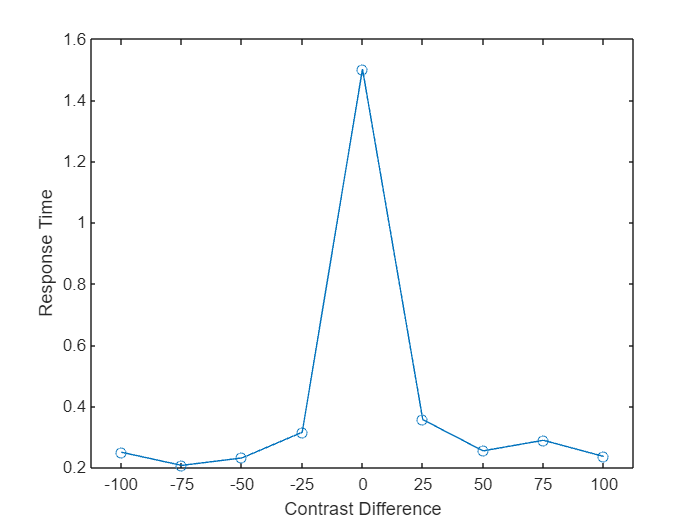

% Calculate New Value
data.response_time_corrected = data.response_time - data.gocue_time;

% Calculate Group Statistics
summ = grpstats(data, "contrast_diff", "median", "DataVars", "response_time_corrected");

% Make Plot
plot(categorical(summ.contrast_diff), summ.median_response_time_corrected, 'o-')
xlabel('Contrast Difference')
ylabel('Response Time')

Instead of calculating the `contrast_diff`, let's calculate the `contrast_diff_absolute`, where the absolute value of the contrast difference is used, so it is  always positive.  This more-closely shows the decision that the mice had to make, and allows us to use twice as many values for each point  estimation.

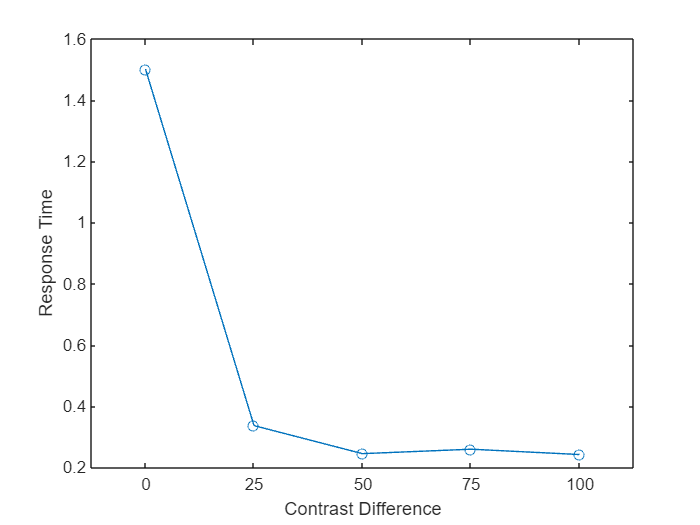

% Calculate New Value
data.contrast_diff_absolute = abs(data.contrast_diff);

% Calculate Group Statistics
summ = grpstats(data, "contrast_diff_absolute", "median", "DataVars", "response_time_corrected");

% Make Plot
plot(categorical(summ.contrast_diff_absolute), summ.median_response_time_corrected, 'o-')
xlabel('Contrast Difference')
ylabel('Response Time')

### Putting Error Bars on Plots

When we calculate these group statistics in experimental science, it's good to represent them as *estimates* of a value you're trying to find.  To do this, we need to calculate and plot errorbars on our plots.

*Example: *Make a point plot showing the mean reaction_type for each mouse.  Include 95% CI error bars.

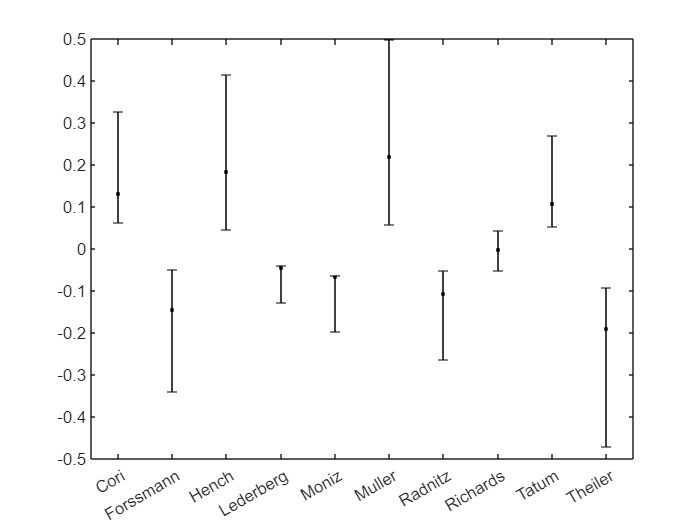

summ = grpstats(data, "mouse", ["mean", "meanci"], "DataVars", "reaction_type");

% Make an errobar plot with *just* the errorbars (no line connecting them)
er = errorbar(categorical(summ.mouse), summ.mean_reaction_type, summ.meanci_reaction_type(:, 1), summ.meanci_reaction_type(:, 2));
er.Color = [0 0 0];
er.LineStyle = 'none';

% Add another plot to the same figure
hold on
plot(categorical(summ.mouse), summ.mean_reaction_type, '.k');
hold off

Make a point plot showing the mean reaction_type for each `contrast_left` level.  Include 95% CI error bars.

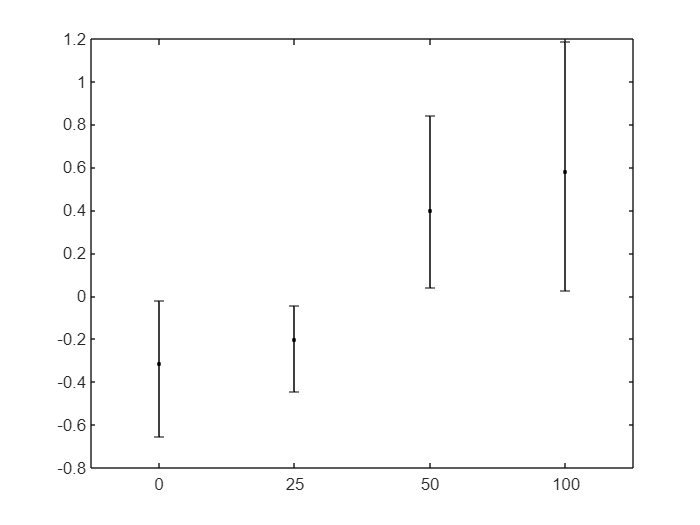

summ = grpstats(data, "contrast_left", ["mean", "meanci"], "DataVars", "reaction_type");

% Make an errobar plot with *just* the errorbars (no line connecting them)
er = errorbar(categorical(summ.contrast_left), summ.mean_reaction_type, summ.meanci_reaction_type(:, 1), summ.meanci_reaction_type(:, 2));
er.Color = [0 0 0];
er.LineStyle = 'none';

% Add another plot to the same figure
hold on
plot(categorical(summ.contrast_left), summ.mean_reaction_type, '.k');
hold off

Make a bar plot showing the mean reaction_type for each `contrast_left` level.  Include 95% CI error bars. (Note: make sure the bars don't hide the error bars.)

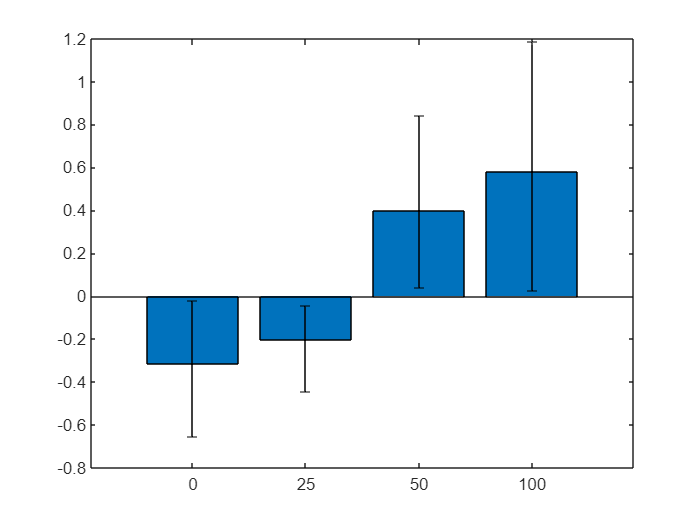

summ = grpstats(data, "contrast_left", ["mean", "meanci"], "DataVars", "reaction_type");

bar(categorical(summ.contrast_left), summ.mean_reaction_type);

hold on
er = errorbar(categorical(summ.contrast_left), summ.mean_reaction_type, summ.meanci_reaction_type(:, 1), summ.meanci_reaction_type(:, 2));
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

Make a bar plot showing the mean reaction_type for each contrast_right level.  Use the standard deviation (`std)` to make the error bars.

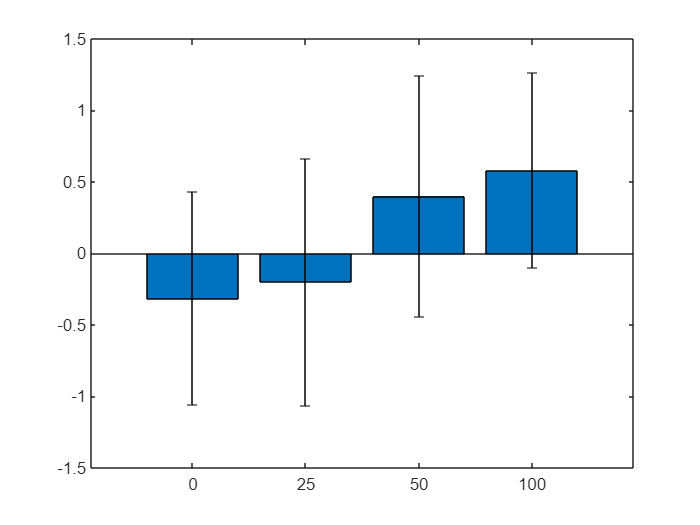

summ = grpstats(data, "contrast_left", ["mean", "std"], "DataVars", "reaction_type");

bar(categorical(summ.contrast_left), summ.mean_reaction_type);

hold on
er = errorbar(categorical(summ.contrast_left), summ.mean_reaction_type, summ.std_reaction_type);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

Make a point plot showing the mean reaction_type for each contrast_right level.  Use the standard error of the mean (`sem) `to make the error bars.

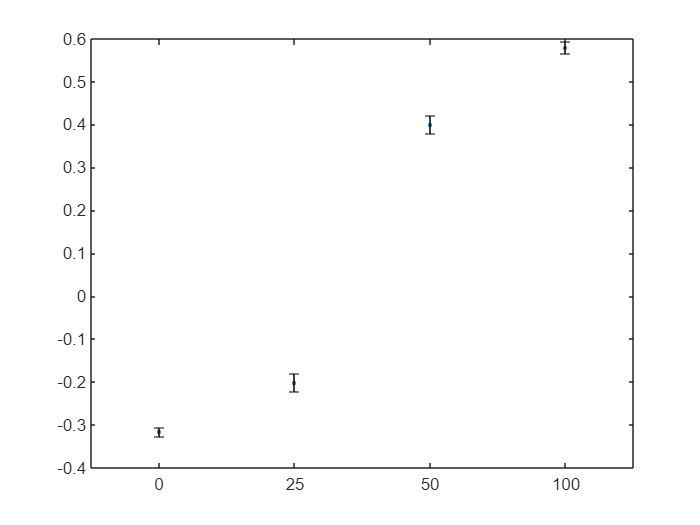

summ = grpstats(data, "contrast_left", ["mean", "sem"], "DataVars", "reaction_type");

plot(categorical(summ.contrast_left), summ.mean_reaction_type, '.');

hold on
er = errorbar(categorical(summ.contrast_left), summ.mean_reaction_type, summ.sem_reaction_type);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off

### **Extra Demonstration: Exporting a Figure**

*Example*: How multiple lines can be plotted on the same figure. It makes a plot the mean, median and standard deviation of response type, grouped by contrast difference and save it to a .pdf file.

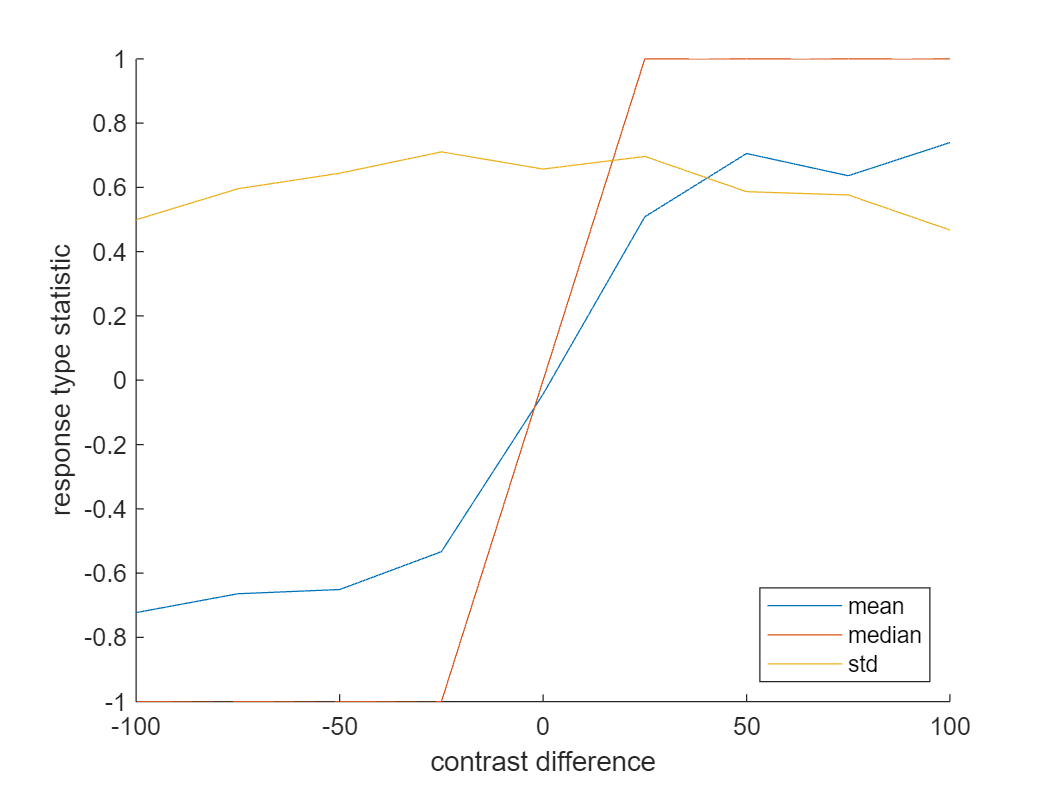

% generate statistics
summ = grpstats(data, "contrast_diff", ["mean","median","std"], "DataVars", "response_type");

% Make the Plot
clf % clear the figure
hold on % freeze the figure for multiple lines
plot(summ.contrast_diff, summ.mean_response_type, "DisplayName","mean")
plot(summ.contrast_diff, summ.median_response_type, "DisplayName","median")
plot(summ.contrast_diff, summ.std_response_type, "DisplayName","std")
hold off % unfreeze

legend ("Location", "southeast") % show legend and set position
xlabel('contrast difference')
ylabel('response type statistic')

% Save the figure
fig_width = 12;
fig_height = 8;
set(gcf, 'PaperPosition', [0 0 fig_width fig_height]); %Position plot at left hand corner with width 5 and height 5. 
set(gcf, 'PaperSize', [fig_width fig_height]);
saveas(gcf, 'my_figure.pdf')